# Transformada de Fourier Discreta

[⇦ Información general del análisis de Fourier](matlab: OpenOverview)

**Objetivos de aprendizaje**

- Graficar la transformada de Fourier discreta (DFT).

- Usar la función fft para calcular la DFT.

- Relacionar la DFT con la transformada de Fourier.

- Aplicar la DFT para analizar una señal de audio.

## Introducción

La transformada de Fourier se puede utilizar para resolver el contenido de frecuencia de una función analítica.

*Senoide modulada por una gaussiana en los dominios del tiempo y la frecuencia.*

Sin embargo, las señales reales son típicamente secuencias discretas de valores medidos, no funciones analíticas. Para tales señales, la transformada de Fourier no se puede aplicar directamente.

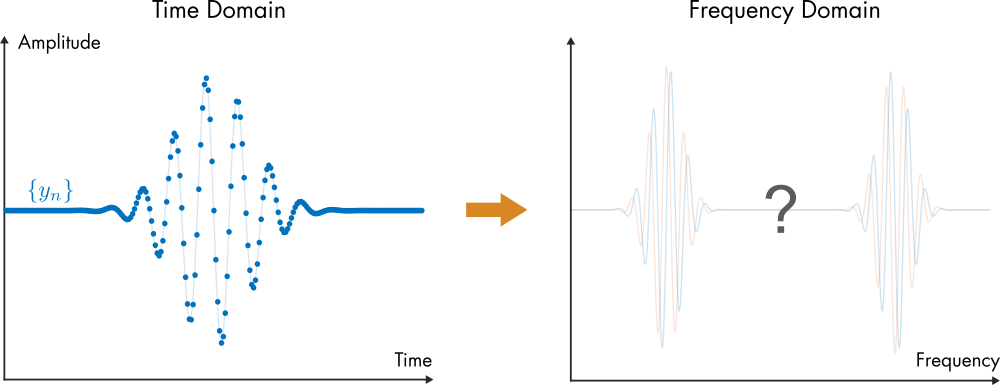

*Una señal discreta *$[y_n]$ *muestreada de una función analítica. ¿Cómo se verá en el dominio de la frecuencia?*

Para analizar una señal discreta en el dominio de la frecuencia, se puede usar la Transformada de Fourier Discreta (DFT, por sus siglas en inglés). La DFT es probablemente la herramienta de análisis de Fourier más utilizada ya que la mayoría de las señales reales contienen mediciones discretas. A menudo encontrarás la DFT bajo un nombre diferente: la FFT (Transformada de Fourier Rápida). No te confundas, sin embargo, son fundamentalmente lo mismo. La FFT es simplemente un algoritmo que calcula la DFT, como ya habrás adivinado, más rápido.

## Definición

La DFT es similar a la serie de Fourier compleja y la Transformada de Fourier. La diferencia esencial es que opera completamente en términos de secuencias discretas, sin referencia alguna a funciones continuas. La DFT se define como


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


El resultado es una secuencia de $N$ valores discretos $[Y_k]$ que representan $[y_n]$ en el dominio de la frecuencia. El resultado $[Y_k]$ es análogo a la transformada de Fourier $\hat{y}(\omega)$, pero más sobre eso más adelante.

## Cálculo de la DFT

**Ejemplo.** En este ejemplo, se calcula la DFT de una señal de audio sintetizada directamente a partir de la definición.

**Tarea.** Primero, crea los puntos de datos ejecutando esta sección.

  **Consejo profesional.** Para ejecutar una sección rápidamente, usa el atajo de teclado **Ctrl+Enter**.

[t,y,Fs] = sineGaussData; % Función auxiliar que genera los datos

figure
plot(t,y,'.')
xlabel("t (s)")
ylabel("y")

Intenta hacer zoom en la señal (usa la herramienta de zoom  ) para examinar más de cerca los puntos de datos discretos $y_n$. ¿Ves algún patrón?

**Tarea.** Ejecuta esta sección para reproducir la señal generada como un clip de audio.

% Este código reproducirá la señal de audio
soundsc(y,Fs)

**Tarea.** Ejecuta esta sección para calcular la DFT usando la definición. Ten en cuenta que las funciones [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) y [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) se utilizan para medir el tiempo necesario para calcular la DFT de N puntos.

N = numel(y); % El número de muestras en y
n = 0:(N-1); % Índices
Y = zeros(N,1);
tic
% Recorre los índices de Yk
for k = 0:(N-1)
    % Calcula la suma y coloca el resultado en Y
    Y(k+1) = sum( y.*exp(-2*pi*1i*k*n/N) );
end
toc

**Tarea.** Ejecuta esta sección para trazar las componentes real e imaginaria de la DFT almacenadas en `Y`.

plot(real(Y),".-")
hold on
plot(imag(Y),".-")
hold off
xlabel("k")
ylabel("Y_k")
% xlim([300 350])

- Intenta hacer zoom en la señal para ver la DFT cerca de los picos. Puedes usar la herramienta de zoom ( ) o descomentar la línea `xlim([300 350])`.

### Transformada de Fourier Rápida (FFT)

En el ejemplo anterior, se calculó la DFT utilizando un bucle for, lo que requiere $O(N^2)$ cálculos. La notación $O(N^2)$ significa que el costo computacional escala como el cuadrado de $N$ (el número de puntos de datos). Esto es muy ineficiente en comparación con la Transformada de Fourier Rápida (FFT, por sus siglas en inglés). El algoritmo FFT descompone la DFT en DFT más pequeñas y luego combina los resultados para formar la DFT completa. La FFT solo requiere $O(N\log(N))$ operaciones. Esto implica que la FFT puede ser miles de veces más rápida que la DFT para conjuntos de datos grandes.

** Ejercicio.** En este ejercicio, calcularás la DFT utilizando el algoritmo FFT.

**Tarea 1.** Primero, crea los puntos de datos ejecutando esta sección.

[t,y,Fs] = sineGaussData; % Función auxiliar que genera los datos

**Tarea 2.** Usa la función [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) para calcular la DFT de `y` y almacena el resultado en `Y`.

% Escribe tu código aquí


tic
Y = fft(y);
toc

**Tarea 3.** Rodea la llamada a la función fft en la Tarea 2 con los comandos [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) y [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html)  para medir cuánto tiempo se tarda en calcular la FFT. Compara esto con la cantidad de tiempo requerido usando la definición en la sección anterior. ¿Cuánto más rápida es la FFT?

**Tarea 4.** Traza las componentes real e imaginaria de Y. Para extraer las componentes real e imaginaria, usa las funciones [`real`](https://www.mathworks.com/help/matlab/ref/real.html) e [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html). Usa los comandos [`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) para continuar trazando en los mismos ejes.

% Escribe tu código aquí


plot(real(Y),".-")
hold on
plot(imag(Y),".-")
hold off
xlabel("k")
ylabel("Y_k")

Si es correcto, tu resultado debería ser idéntico al gráfico de DFT del ejemplo anterior.

## Comparación de la DFT con la Transformada de Fourier

La senoide modulada por una gaussiana es útil para comparar la DFT y la transformada de Fourier porque se conoce la forma analítica. Probablemente notaste que la DFT se parece a lo que esperarías de la transformada de Fourier de la senoide modulada por una gaussiana. 

Los puntos de datos discretos en la sección anterior se muestrearon a partir de una función continua. Para comprender mejor lo que se calcula mediante la DFT, es útil examinar la transformada de Fourier de la función original.

**Tarea.** Ejecuta esta sección para mostrar el gráfico analítico.

plotFourierTransform
% xlim([650 750])
 

 Reflexionar. 

- ¿A qué picos en la DFT corresponden los picos de la transformada de Fourier?

- Intenta hacer zoom en la señal para ver la DFT cerca de los picos. Puedes usar la herramienta de zoom ( ) o descomentar la línea `xlim([650 750])`.

- ¿Cómo se compara la transformada de Fourier de la señal con la DFT?

Para comprender las diferencias entre los gráficos de la transformada de Fourier y la DFT, compara las definiciones de la DFT y la transformada de Fourier. La DFT:


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


La transformada de Fourier:


$$\hat{y}(\omega) = \int_{-\infty}^\infty y(t) e^{-i\omega t} \ dt$$


Observa las similitudes:

- La suma de la DFT aproxima la integral

- Los dos factores corresponden entre las definiciones $ y_n \leftrightarrow y(t)$ y $e^{- \frac{ 2 \pi i k n }{N }} \leftrightarrow  e^{-i\omega t} $. 

Observa dos diferencias esenciales:

- El  de la integral escala la transformada de Fourier $\hat{y}$, pero el resultado de la DFT, $Y_k$, no está escalado por un $\Delta t$.

- El exponencial complejo se da en términos de índices discretos:  y , en lugar de variables continuas, $\omega$ y $t$.

 **Ejemplo.** En el ejemplo, la DFT se relacionará con la transformada de Fourier utilizando la senoide modulada por una gaussiana.

Tarea. Ejecuta esta sección para calcular la DFT utilizando la función [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html).

[t,y,Fs] = sineGaussData; % Función auxiliar que genera los datos
Y = fft(y);

La transformada de Fourier está escalada (en amplitud) por $dt$. El análogo discreto de $dt$ es el paso de tiempo $\Delta t$ en la señal muestreada. El paso de tiempo $\Delta t = 1/f_s$, donde $f_s$ es la frecuencia de muestreo. Esto implica que, para reescalar la salida $Y$ para que coincida con $\hat{y}$, puedes multiplicar por `1/Fs`.

**Tarea.** Ejecuta esta sección para reescalar `Y` y graficar el resultado. Compara la escala del eje vertical con el resultado de la transformada de Fourier analítica.

N = length(Y);
k = 0:(N-1);
Yrescaled = 1/Fs*Y;
realImagPlot(k,Yrescaled,"$k$","$\frac{1}{f_s}Y_k$"); % Función auxiliar que crea la gráfica

También puedes usar la tasa de muestreo $f_s$ para relacionar los índices discretos $k$ y $n$ con las variables continuas $\omega$ y $t$. Igualar estos términos en los exponenciales de cada definición:


$$  \frac{2 \pi kn}{N} = t \omega$$


La discretización de $t$ como $n\Delta t = n/f_s$ implica que las frecuencias discretas son


$$\omega_k = \frac{ 2 \pi k f_s}{   N}$$


**Tarea.** Ejecuta esta sección para trazar el resultado de la DFT frente a las frecuencias angulares $\omega_n$.

omega = 2*pi*k*Fs/N;
realImagPlot(omega,Yrescaled,"$\omega$","$\frac{1}{f_s}Y_k$"); % Función auxiliar que crea la gráfica

Compara las frecuencias angulares de la DFT a lo largo del eje -$\omega$ con las de la transformada de Fourier. ¿Los picos están en el mismo lugar? Puedes identificar las ubicaciones de los picos haciendo clic en la gráfica para crear una herramienta de información sobre herramientas. 

Deberías notar que el primer pico de la DFT coincide con **el segundo** pico de la transformada de Fourier. Esto se debe a la definición de la DFT (que tiene consecuencias inesperadas). Puedes usar la función [`fftshift`](https://www.mathworks.com/help/matlab/ref/fftshift.html) para alinear la DFT con la transformada de Fourier.

**Tarea.** Ejecuta esta sección para reorganizar los valores de la DFT, $[Y_k]$, para que se alineen con la transformada de Fourier $\hat{y}$. Los valores de $\omega$ también se regeneran para corresponder a las frecuencias desplazadas.

% Desplaza los valores de Y
Yshift = fftshift(Yrescaled);
% Desplaza la frecuencia angular
omegaShift = 2*pi*Fs/N*(-N/2:N/2-1);

realImagPlot(omegaShift,Yshift,"$\omega$","$\frac{1}{f_s}Y_k$"); % Función auxiliar que crea la gráfica
xlim([-1000 1000])

**Tarea.** Ejecuta esta sección para trazar los valores de la DFT desplazada (`Yshift`) junto con la transformada de Fourier.

plotDFTandTransform(omegaShift,Yshift);
% xlim([650,750])

- Intenta hacer zoom en la señal para ver la DFT cerca de los picos. Puedes usar la herramienta de zoom ( ) o descomentar la línea `xlim([650,750])`.

## Analizando una señal de audio

La FFT se utiliza comúnmente para analizar el contenido en el dominio de frecuencia de las señales medidas. Este es uno de los métodos esenciales en el procesamiento de señales.

 **Ejercicio.** En este ejercicio, analizarás las frecuencias presentes en una nota de guitarra.

**Tarea 1.** Ejecuta esta sección para leer el archivo MP3 y trazar la señal. El contenido de la señal se almacena en `g`.

% Este código reproduce el sonido de la guitarra y traza parte de la señal
[g2Ch,Fs] = audioread("Anote.mp3");
g = g2Ch(:,1); % Solo usa el primer canal de audio
soundsc(g,Fs)
plotGuitarSignal(g,Fs)

- Intenta hacer zoom en la señal ( ) para ver el contenido en el dominio del tiempo.

**Tarea 2.** Calcula la DFT de la señal `g` usando [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html). Almacena el resultado en `G`.

% Escribe tu código aquí
G = fft(g);

Tarea 3. Reescala `G` multiplicándolo por `1/Fs` (`Fs` contiene la frecuencia de muestreo). Esto relaciona el eje vertical de `G` con la transformada de Fourier. Almacena el resultado en `Gescalado`.

% Escribe tu código aquí
Gscaled = G*1/Fs;

**Tarea 4.** El resultado de FFT tiene más sentido después de que el "contenido de alta frecuencia" se desplaza a frecuencias negativas. Usa [`fftshift`](https://www.mathworks.com/help/matlab/ref/fftshift.html) para realizar esta operación en `Gescalado` y almacena el resultado en `Gshift`.

% Escribe tu código aquí
Gshift = fftshift(Gscaled);

**Tarea 5.** Calcula las frecuencias angulares que corresponden a `GShift` y almacénalas en un vector omega. Las frecuencias angulares (en rad/s) que corresponden al resultado de `fftshift` son

 
$$\omega_k = \frac{ 2 \pi k f_s}{   N}$$


donde $f_s$ es la frecuencia de muestreo, $N$ es el número de muestras y $k$ varía de $-N/2$ a $N/2-1$.

**Pista:** Comienza por calcular la longitud de la señal g y almacena el resultado en `N`. La frecuencia de muestreo ya está almacenada en la variable `Fs`.

% Write your code here
N = numel(g);
omega = 2*pi*Fs/N*(-N/2:N/2-1);

**Tarea 6.** Trazar las componentes real e imaginaria de `Gshift` frente a `omega`. 

**Pista:** Para extraer las componentes real e imaginaria, usa las funciones [`real`](https://www.mathworks.com/help/matlab/ref/real.html) e [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html). Usa comandos [`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) para continuar trazando en los mismos ejes.

figure % Crea una nueva figura
% Escribe tu código aquí
plot(omega,real(Gshift))
hold on
plot(omega,imag(Gshift))
hold off
xlim([-1e4 1e4])
xlabel("$\omega$","Interpreter","latex")
ylabel("$\hat{g}$","Interpreter","latex")

Haz zoom en la gráfica (usando la herramienta de zoom   o [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html)). Si tus cálculos son correctos, deberías ver esta gráfica:

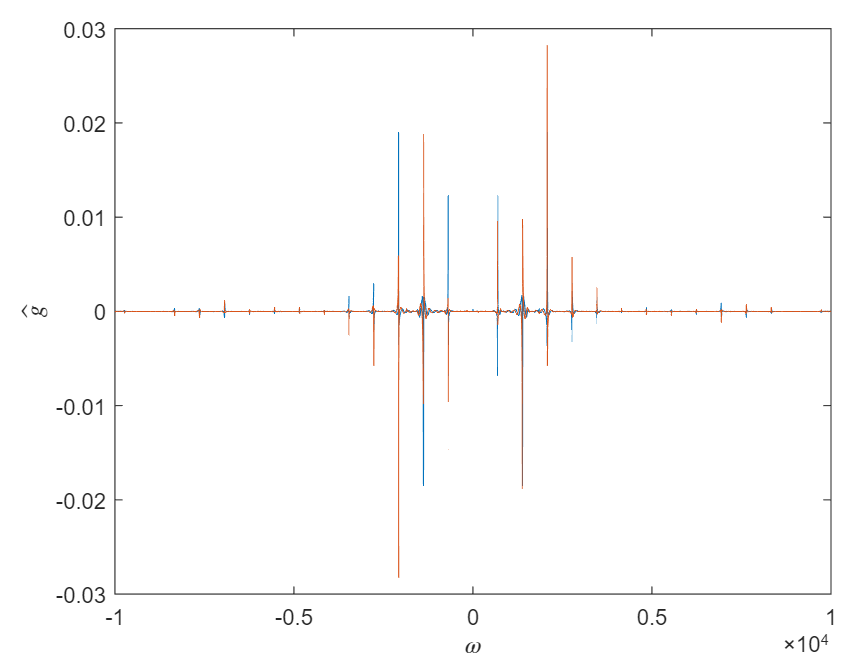

En lugar de mirar las componentes real e imaginaria de $G$, a menudo es más útil mirar la magnitud.

**Tarea 7**. Calcula la magnitud de `Gshift` usando [`abs`](https://www.mathworks.com/help/matlab/ref/abs.html). Almacena el resultado en `Gabs`. Luego, traza `Gabs` frente a `omega`.

% Escribe tu código aquí

Gabs = abs(Gshift);
plot(omega,Gabs)
xlabel("$\omega$","Interpreter","latex")
ylabel("$|\hat{g}|$","Interpreter","latex")

**Tarea 8.** Trazar frente a la frecuencia angular $\omega$ (dada en rad/s) es útil para comparar con la transformada de Fourier, pero menos útil para entender señales reales. 

- Calcula las frecuencias en Hz a partir de omega y almacena el resultado en freq. 

- Traza Gabs frente a freq.

- Gran parte del contenido de frecuencia se encuentra entre -1 kHz y 1 kHz, así que ajusta los límites del eje a ese rango.

% Write your code here
freq = omega/(2*pi);
plot(freq,Gabs)
xlabel("f (Hz)")
ylabel("|g|")
xlim([-1000 1000])

**Tarea 9.** Esta señal proviene de una sola cuerda de guitarra que se ha pulsado. ¿De qué cuerda proviene (E grave, A, D, G, B o E agudo)? Registra tu respuesta en el espacio de abajo.

**Pistas:**

- Recuerda que una sola cuerda vibrará con una frecuencia fundamental y varios armónicos.

- Puedes hacer clic en un pico en el dominio de la frecuencia para crear una información sobre herramientas.

- A continuación se muestra una tabla con algunas de las notas relevantes.

 
$$\text{\textbf{Octava 2}}
\\
\begin{array}{lr} 
\text{Nota} & \text{ Hz} \\
C & 65.4 \\ 
C\# & 69.3 \\
D & 73.4 \\
D\# & 77.8\\
E & 82.4\\
F & 87.3 \\
F\# & 92.5 \\
G & 98.0\\
G\# & 103.8\\
A & 110.0\\
A\# & 116.5\\
B & 123.5\\
\end{array}$$
                
$$\text{\textbf{Octava 3}}
\\
\begin{array}{lr} 
\text{Nota} & \text{ Hz} \\
C & 130.8 \\ 
C\# & 138.6 \\
D & 146.8\\
D\# & 155.6\\
E & 164.8\\
F & 174.6 \\
F\# & 185.0 \\
G & 196.0\\
G\# & 207.7\\
A & 220.0\\
A\# & 233.1\\
B & 246.9\\
\end{array}$$
                
$$\text{\textbf{Octava 4}}
\\
\begin{array}{lr} 
\text{Nota} & \text{ Hz} \\
C & 261.6 \\ 
C\# & 277.2 \\
D & 293.7\\
D\# & 311.1\\
E & 329.6\\
F & 349.2\\
F\# & 370.0\\
G & 392.0\\
G\# & 415.3\\
A & 440.0\\
A\# & 466.2\\
B & 493.9\\
\end{array}$$


% Registra tu respuesta (E, A, D, G o B) entre las comillas
nota = "";

[⇦ Descripción general del análisis de Fourier](matlab: OpenOverview)

**Funciones auxiliares**

function [t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData
% Muestrea un sinusoidal modulado por una gaussiana

Fs = 2e3; % Tasa de muestreo de audio

% Datos de la función sinusoidal modulada por una gaussiana
A = 1.5; % Amplitud
f0 = 110; % Frecuencia portadora (Hz)
c = 0.3; % "Ancho" gaussiano
t0 = 1; % Posición central (s)
omega0 = f0*2*pi; % Frecuencia angular (rad/s)

% Discretización
tLims = [0 3];
N = round(Fs*(tLims(2)-tLims(1)));
t = (0:1/Fs:N/Fs-1/Fs) + tLims(1);
y = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));
end

function plotFourierTransform
% Traza la transformada de Fourier de la función sinusoidal modulada por una gaussiana

% Datos de la función
[t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData;

% Parámetros de trazado
omegaLims = 2*pi*[-150 150];

% Calcula la transformada
omega = linspace(omegaLims(1),omegaLims(2),2e4);
yhat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
    exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

% Crea las gráficas
figure("Position",[1 1 800 400])
subplot(1,2,1)
plot(t,y)
xlim(tLims)
xlabel("$t$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
title("Dominio del tiempo","Interpreter","latex")

subplot(1,2,2)
plot(omega,real(yhat))
hold on
plot(omega,imag(yhat))
hold off
xlim([omega(1),omega(end)])
xlabel("$\omega$ (rad/s)","Interpreter","latex")
ylabel("$\hat{y}$","Interpreter","latex")
legend("Re$(\hat{y})$","Im$(\hat{y})$","Interpreter","latex","Location","south");
title("Dominio de la frecuencia","Interpreter","latex")

end

function realImagPlot(x,y,xLabel,yLabel)
% Crea una gráfica compleja con las etiquetas dadas

figure
plot(x,real(y),".-")
hold on
plot(x,imag(y),".-")
hold off
xlabel(xLabel,"Interpreter","latex")
ylabel(yLabel,"Interpreter","latex")
end

function plotDFTandTransform(omegaShift, Yshift)
% Traza la DFT en Yshift y la transformada de Fourier de la función sinusoidal modulada por una gaussiana

colors = lines(2);

% Traza la DFT
figure
plot(omegaShift,real(Yshift),".","MarkerSize",8)
hold on
plot(omegaShift,imag(Yshift),".","MarkerSize",8)
hold off

% Calcula la transformada y la traza
[t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData;
% Parámetros de trazado
omegaLims = 2*pi*[-150 150];
% Calcula la transformada
omega = linspace(omegaLims(1),omegaLims(2),2e4);
yhat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
    exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

hold on
plot(omega,real(yhat),"color",colors(1,:)*0.75)
plot(omega,imag(yhat),"color",colors(2,:)*0.75)
hold off
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{y}$","Interpreter","latex")
    legend("Re$(Y_k)$","Im$(Y_k)$",...
           "Re$(\hat{y})$","Im$(\hat{y})$",...
           "Interpreter","latex","Location","eastoutside");
    title("Frequency Domain","Interpreter","latex")
end

function plotGuitarSignal(yGuitar,FsGuitar)
    % Traza la señal de guitarra en el dominio del tiempo

    tGuitar = (1:length(yGuitar))/FsGuitar; % Variable de tiempo    
    % Genera la gráfica
    figure("position",[1,1,800,400]) 
    plot(tGuitar,yGuitar(:,1),"Linewidth",1)
    xlabel("$t$ (s)","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Dominio del tiempo","Interpreter","latex")
end

% Sugerencias no utilizadas
%#ok<*ASGLU>